# **Constantes**

C_max    = 15;        %ml/mmHg
C_min    = 0.4;       %ml/mmHg
C_art    = 2;         %ml/mmHg
I_art    = 10^(-4);   %mmHg.s²/ml
p_LA     = 8;         %mmHg
p_RA     = 3;         %mmHg
R_hArt   =  0.1;      %mmHg.s/ml
R_hCap   = 1;         %mmHg.s/ml
R_AV     = 0.1;       %mmHg.s/ml
R_MV     = 10^(-2);   %mmHg.s/ml
V_r      = 5;         %ml
T_ccRef  = 6/7;       %s

# **Defin C_LV  **


%T_cc = 1; %able to choose cardiac rythm time
T_cc = 6/7; %60BPM

T_vc = 0.3*(T_cc/T_ccRef);
T_vr = 0.15*(T_cc/T_ccRef);

ecc1 = @(t) (0.5 * (1 - cos(pi * t / T_vc)));
ecc2 = @(t) (0.5 * (1 + cos(pi* (t-T_vc) / T_vr)));
ecc3 = @(t) (0);


syms t real
ecc(t) = piecewise((0 < t) & (t <= T_vc), ecc1, (T_vc < t) & (t < T_vc + T_vr), ecc2,  (T_vc + T_vr < t) & (t <= T_cc), ecc3,0) %On peut enlever le dernier 0 ça change rien

$$ecc(t) = \left\{ \begin{array}{cl} \frac{1}{2}-\frac{\cos\left(\frac{10\,\pi \,t}{3}\right)}{2} & \text{ if }t\in \left(0,\frac{3}{10}\right]\\ \frac{\cos\left(\frac{20\,\pi \,\left(t-\frac{3}{10}\right)}{3}\right)}{2}+\frac{1}{2} & \text{ if }t\in \left(\frac{3}{10},\frac{9}{20}\right)\\ 0 & \mathrm{otherwise} \end{array}\right.$$

C_LV(t) = 1 / ( ( 1/C_min - 1/C_max ) * ecc(mod(t,T_cc)) + 1/C_max)

$$C\_LV(t) = \left\{ \begin{array}{cl} -\frac{1}{\frac{73\,\cos\left(\frac{10\,\pi \,\left(t\mathrm{mod}\frac{6}{7}\right)}{3}\right)}{60}-\frac{77}{60}} & \text{ if }t\mathrm{mod}\frac{6}{7}\in \left(0,\frac{3}{10}\right]\\ \frac{1}{\frac{73\,\cos\left(\frac{20\,\pi \,\left(\left(t\mathrm{mod}\frac{6}{7}\right)-\frac{3}{10}\right)}{3}\right)}{60}+\frac{77}{60}} & \text{ if }t\mathrm{mod}\frac{6}{7}\in \left(\frac{3}{10},\frac{9}{20}\right)\\ 15 & \mathrm{otherwise} \end{array}\right.$$

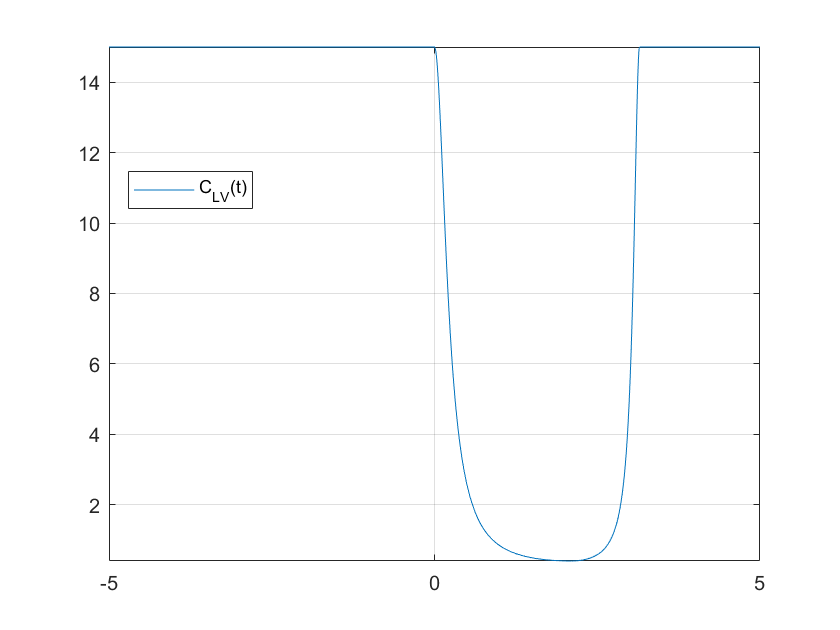


fplot(C_LV(t))
grid on
legend('C_{LV}(t)','Location','best')

%f_CLV = odeFunction(C_LV,t);
syms t
d_C_LV(t) = diff(C_LV,t,1)

$$d\_C\_LV(t) = \begin{array}{l} \left\{ \begin{array}{cl} -\frac{73\,\pi \,\sin\left(\sigma_{2}\right)\,\sigma_{3}}{18\,{\left(\frac{73\,\cos\left(\sigma_{2}\right)}{60}-\frac{77}{60}\right)}^{2}} & \text{ if }t\mathrm{mod}\frac{6}{7}\in \left(0,\frac{3}{10}\right)\\ \frac{73\,\pi \,\sin\left(\sigma_{1}\right)\,\sigma_{3}}{9\,{\left(\frac{73\,\cos\left(\sigma_{1}\right)}{60}+\frac{77}{60}\right)}^{2}} & \text{ if }t\mathrm{mod}\frac{6}{7}\in \left(\frac{3}{10},\frac{9}{20}\right)\\ 0 & \mathrm{otherwise} \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{20\,\pi \,\left(\left(t\mathrm{mod}\frac{6}{7}\right)-\frac{3}{10}\right)}{3}\\ \sigma_{2}=\frac{10\,\pi \,\left(t\mathrm{mod}\frac{6}{7}\right)}{3}\\ \sigma_{3}=\frac{\partial }{\partial t}\left(t\mathrm{mod}\frac{6}{7}\right) \end{array}$$

d_C_LV(35/100)

$$ans = \frac{58400\,\pi \,\sqrt{3}\,\left({\left(\frac{\partial }{\partial t}\left(t\mathrm{mod}\frac{6}{7}\right)\right)|}_{t=\frac{7}{20}}\right)}{51529}$$

fplot(d_C_LV(t))
grid on
legend('C_{LV}(t)','Location','best')
%f_CLV = odeFunction(C_LV,t);
syms t
d_C_LV(t) = diff(C_LV,t,1)

# **Sytèmes d'équation différentiels**

syms p_LV(t) Q2(t) p1(t)
 
%ode1 = C_LV*diff(p_LV,t,1) == -p_LV*diff(C_LV,t,1) + ((p_LA - p_LV) / R_MV) * heaviside(p_LA - p_LV) - ((p_LV - p1) / R_AV) * heaviside(p_LV - p1)             
ode1 =  (8* cos(t) + 8) * diff(p_LV,t,1) == -p_LV * -8 * sin(t) + ((p_LA - p_LV) / R_MV) * heaviside(p_LA - p_LV) - ((p_LV - p1) / R_AV) * heaviside(p_LV - p1)                

$$ode1(t) = \left(8\,\cos\left(t\right)+8\right)\,\frac{\partial }{\partial t}p_{\mathrm{LV}}\left(t\right)=8\,p_{\mathrm{LV}}\left(t\right)\,\sin\left(t\right)-\mathrm{heaviside}\left(8-p_{\mathrm{LV}}\left(t\right)\right)\,\left(100\,p_{\mathrm{LV}}\left(t\right)-800\right)+\mathrm{heaviside}\left(p_{\mathrm{LV}}\left(t\right)-p_{1}\left(t\right)\right)\,\left(10\,p_{1}\left(t\right)-10\,p_{\mathrm{LV}}\left(t\right)\right)$$

ode2 = I_art*diff(Q2,t,1) == p1 - p_RA - (R_hCap + R_hArt) * Q2

$$ode2(t) = \frac{\frac{\partial }{\partial t}Q_{2}\left(t\right)}{10000}=p_{1}\left(t\right)-\frac{11\,Q_{2}\left(t\right)}{10}-3$$

ode3 = C_art*diff(p1,t,1) ==  C

Unrecognized function or variable 'C'.

 
odes = [ode1;ode2;ode3];
 
%TODO CONDITION LIMITE et à vérifier
cond1 = p_LV(0) == 150
cond2 = Q2(0) == 120
cond3 = p1(0) == 70
conds = [cond1;cond2;cond3];

%[p_LVsol(t), Q2sol(t), p1sol(t)] = dsolve(odes,conds)
[p_LVsol(t), Q2sol(t), p1sol(t)] = dsolve(odes)

# **Graphiques**

% fplot(p_LVsol)
% hold on
% fplot(Q2sol)
% fplot(p1sol)
% grid on
% legend('p_{LV}','Q_2','p_1','Location','best')